# ME 140 - Ch 12 Iterative Methods - In Class 10.14

## Problem 12.2

Use the Gauss-Seidel method to solve the following system until the percent relative error falls below 5%.

Use overrelaxation with lamda = 1.2 for part b

help GaussSeidel.m

  GaussSeidel: Gauss Seidel method
  [x,ea,iter] = GaussSeidel(A,b,es,maxit): Gauss Seidel without relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



A = [0.8 -0.4 0; -0.4 0.8 -0.4; 0 -0.4 0.8];
b = [41; 25; 105];

es = 5;
[x5,ea5,iter5] = GaussSeidel(A,b,es)

x5 =   167.8711
  239.1211
  250.8105


ea5 = 3.5020

iter5 = 6

            % 6 iterations required w/o relaxation
[x,ea,iter] = GaussSeidel(A,b)

x =   173.7500
  245.0000
  253.7500


ea = 6.4536e-06

iter = 25


x1 = A\b % simpler

x1 =   173.7500
  245.0000
  253.7500



% With overrelaxation
help GaussSeidelRelax

  GaussSeidel: Gauss Seidel method with relaxation
  [x,ea,iter] = GaussSeidelRelax(A,b,lambda,es,maxit): Gauss Seidel with relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  lambda = relation factor (default = 1)
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



lambda = 1.2;
[x5,ea5,iter5] = GaussSeidelRelax(A,b,lambda,es) 

x5 =   171.4230
  244.3887
  253.6222


ea5 = 4.9971

iter5 = 4

            % 4 iterations required w/ relaxation
[x,ea,iter] = GaussSeidelRelax(A,b,lambda)

x =   173.7500
  245.0000
  253.7500


ea = 6.1014e-06

iter = 12

## Problem 12.16

Determine the roots of the simultaneous nonlinear equations

(x-4)^2+(y-4)^2=5            x^2+y^2=16

Use a graphical approach to obtain your initial guesses. Determine the refined estimates with a) two equation Newton-Raphson b) fsolve

% u = @(x) (x(1)-4)^2+(x(2)-4)^2-5; % CANNOT: need .m file
% v = @(x) x(1)^2+x(2)^2-16;
help meshgrid

 meshgrid   Cartesian rectangular grid in 2-D or 3-D
    [X,Y] = meshgrid(x,y) returns 2-D grid coordinates based on the
    coordinates contained in vectors x and y. X is a matrix where each row
    is a copy of x, and Y is a matrix where each column is a copy of y. The
    grid represented by the coordinates X and Y has length(y) rows and
    length(x) columns.
 
    [X,Y,Z] = meshgrid(x,y,z) returns 3-D grid coordinates defined by the
    vectors x, y, and z. The grid represented by X, Y, and Z has size
    length(y)-by-length(x)-by-length(z).
 
    [X,Y] = meshgrid(x) is the same as [X,Y] = meshgrid(x,x), returning
    square grid coordinates with grid size length(x)-by-length(x).
 
    [X,Y,Z] = meshgrid(x) is the same as [X,Y,Z] = meshgrid(x,x,x),
    returning 3-D grid coordinates with grid size
    length(x)-by-length(x)-by-length(x).
 
    meshgrid

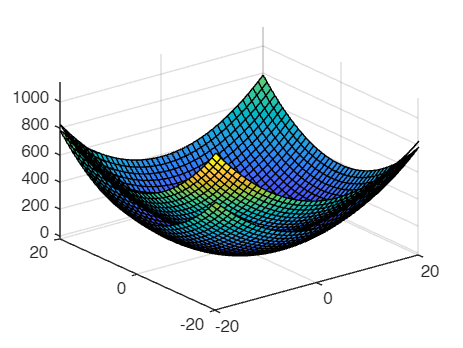

% Create a grid for plotting
[x1, x2] = meshgrid(-20:1:20, -20:1:20);

% Evaluate g(x1, x2) over the grid
G = (x1-4).^2+(x2-4).^2-5;
H = x1.^2+x2.^2-16;

% Plot 3D surface
figure;
surf(x1, x2, G);
hold on;
surf(x1, x2, H);


% Need to use jfreact2 and newtmult
x0 = [2;4];
% Need optimization toolbox setup
help newtmult

  newtmult: Newton-Raphson root zeroes nonlinear systems
  [x,f,ea,iter]=newtmult(func,x0,es,maxit,p1,p2,...):
  uses the Newton-Raphson method to find the roots of
  a system of nonlinear equations
  input:
    func = name of function that returns f and J
    x0 = initial guess
    es = desired percent relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    x = vector of roots
    f = vector of functions evaluated at roots
    ea = approximate percent relative error (%)
    iter = number of iterations



help jfreact2

  jfreact2: Calculates the Jacobian matrix J and the function vector f
            for a system of two nonlinear equations, f1(x1, x2) and f2(x1, x2).
 
  NOTE: This specific implementation uses the finite-difference approximation
        for partial derivatives and assumes the system is defined by two
        external functions, u(x1, x2) and v(x1, x2), where f1=u and f2=v.
 
  input:
    x = current root estimate vector [x1; x2]
    varargin = optional parameters to pass to u and v functions (not used here)
 
  output:
    J = The 2x2 Jacobian matrix of partial derivatives
    f = The 2x1 function vector [f1; f2]
 
  -------------------------------------------------------------------------
  THE JACOBIAN MATRIX (J) STRUCTURE:
 
  J = [ df1/dx1, df1/dx2 ]   -> The first row is the gradient of f1
      [ df2/dx1, df2/dx2 ]   -> The second row is the gradient of f2
  -------------------------------------------------------------------------



func = jfreact2_v2(x0, u, v); % [J, f_jf]

Not enough input arguments.

Error in u (line 5)
fu = (x1-4)^2 + (x2-4)^2 - 5;

%func = jfreact2(x0) % not sure.
[x,f,ea,iter]=newtmult(jfreact2_v2,x0,u,v) % not sure
% The way book does it:
%   function file for u
%   function file for v
%   Just put x0 into jfreact2
%   Put @jfreact2, x0 into newmult

#### Gemini's way

% --- Graphical Approach to Initial Guess ---
% The two equations represent two circles:
% 1. (x-4)^2 + (y-4)^2 = 5  (Center (4, 4), Radius sqrt(5) ~= 2.236)
% 2. x^2 + y^2 = 16          (Center (0, 0), Radius 4)

figure('Name', 'Problem 12.16 Graphical Solution');
clf; % Clear current figure

% 1. Plot the first circle: (x-4)^2 + (y-4)^2 = 5
% We plot the zero contour of the rearranged function u(x, y) = 0
fimplicit(@(x, y) (x-4).^2 + (y-4).^2 - 5, 'LineWidth', 2, 'Color', 'b');
hold on;
axis equal;

% 2. Plot the second circle: x^2 + y^2 = 16
% We plot the zero contour of the rearranged function v(x, y) = 0
fimplicit(@(x, y) x.^2 + y.^2 - 16, 'LineWidth', 2, 'Color', 'r');

x0 = [2 3.5];
es_newt = 0.0001; % desired percent relative error
maxit_newt = 50;  % maximum iterations

[x_newt, f_newt, ea_newt, iter_newt] = newtmult(@jfreact2, x0, es_newt, maxit_newt) % literally all it needs is x. u & v given

x_newt =     1.8058    3.3058
    3.5692    5.0692


f_newt = 1.0e-09 *

    0.1608
    0.1608


ea_newt = 1.0e-08 *

    0.2525    0.1379


iter_newt = 9


disp(['  x (x, y) = [', num2str(x_newt(1)), '; ', num2str(x_newt(2)), ']']);

  x (x, y) = [1.8058; 3.5692]


disp(['  f (residual) = [', num2str(f_newt(1)), '; ', num2str(f_newt(2)), ']']);

  f (residual) = [1.6083e-10; 1.6083e-10]



% --- b) fsolve (MATLAB Optimization Toolbox) ---
% fsolve requires a single function handle that returns the vector f.

fsolve_fun = @(x) [(x(1)-4)^2 + (x(2)-4)^2 - 5; x(1)^2 + x(2)^2 - 16];

disp(' ');

disp('--- b) fsolve Solution ---');

--- b) fsolve Solution ---


% fsolve requires a function that returns f = [f1; f2].
% fsolve_fun.m is needed for this.
[x_fsolve, f_fsolve] = fsolve(fsolve_fun, x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_fsolve =     1.8058    3.5692


f_fsolve = 1.0e-07 *

    0.2506
    0.2507



disp('fsolve Results (Root 1):');

fsolve Results (Root 1):


disp(['  x (x, y) = [', num2str(x_fsolve(1)), '; ', num2str(x_fsolve(2)), ']']);

  x (x, y) = [1.8058; 3.5692]


disp(['  f (residual) = [', num2str(f_fsolve(1)), '; ', num2str(f_fsolve(2)), ']']);

  f (residual) = [2.5065e-08; 2.5069e-08]


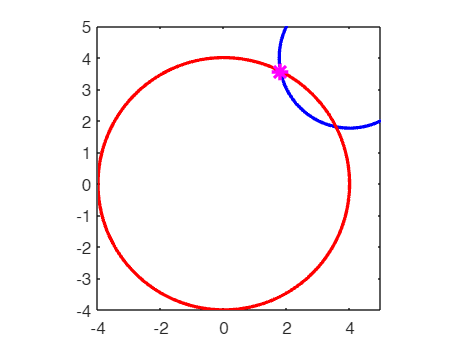


% Mark the fsolve solution on the plot
plot(x_fsolve(1), x_fsolve(2), 'm*', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'fsolve Root');

**Root-finding algorithms are local search methods, not global search methods.**

Here is a breakdown of why fsolve (and newtmult) only found one solution, even though the system has two:

**1. The Role of the Initial Guess (****$\mathbf{x}_0$****)**

fsolve (and the Newton-Raphson method) is designed to find a root *near* the starting point you provide, $\mathbf{x}_0$. The iterative process is like a ball rolling downhill toward a minimum (or in this case, toward a zero).

- **You chose ****$\mathbf{x}_0 = [2.5; 3.0]$****.** This point is in the basin of attraction for the upper-left intersection (Root 1). Therefore, the solver converged quickly to that specific root.

- The solver **cannot "jump"** across the solution space to find another root that is geographically distant from the initial guess.

**2. How to Find the Second Root**

To find the second root (the lower-right intersection), you must supply a new initial guess, $\mathbf{x}_{0, \text{new}}$, that is closer to that other solution.

Looking at the graphical analysis for Problem 12.16, the second intersection appears to be around $\mathbf{x} \approx [3.2; 2.3]$.

You would run the solver again with a different $\mathbf{x}_0$:

## Fsolve

xguess = [2:4];
f_1216 = @(x) [(x(1)-4)^2+(x(2)-4)^2-5; x(1)^2+x(2)^2-16;]

f_1216 = function_handle with value:
    @(x)[(x(1)-4)^2+(x(2)-4)^2-5;x(1)^2+x(2)^2-16]


[x, xf] = fsolve(f_1216, xguess)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =     1.8058    3.5692    4.0000


xf = 1.0e-14 *

    0.3553
    0.3553


% Double check error messages we got